ZSF_st.name='ZSF'; 
ZSF_st.lat=47.42;
ZSF_st.lon=10.98;
ZSF_st.alt=2671;
ZSF_st.env='Mt';
ZSF_st.footp='Mx';

ZSF_rd1=read_betsy('zsf_2009_2017',ZSF_st.name);

ZSF_rd=read_betsy('zsf_2009_2018_longformat',ZSF_st.name);

datevec(ZSF_rd.Time(1))

ans =         2009           1           2           0           0           0


datevec(ZSF_rd.Time(end))

ans =         2019           1           1           0           0           0


prctile(ZSF_rd.U_S11,[5 50 95])

ans =     4.2000   13.0000   23.8925


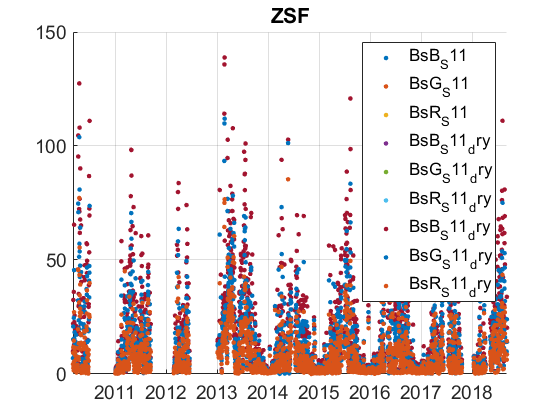

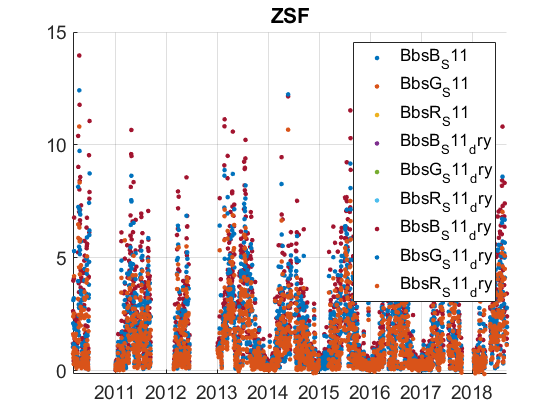

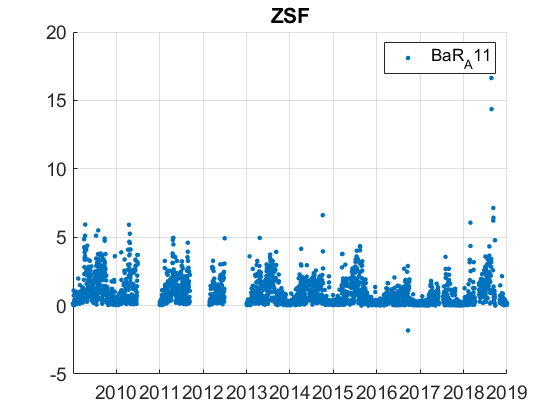

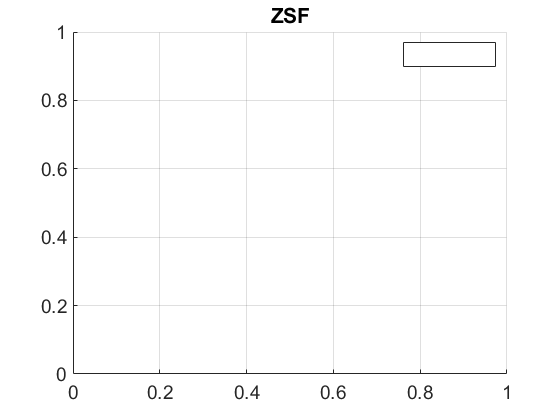

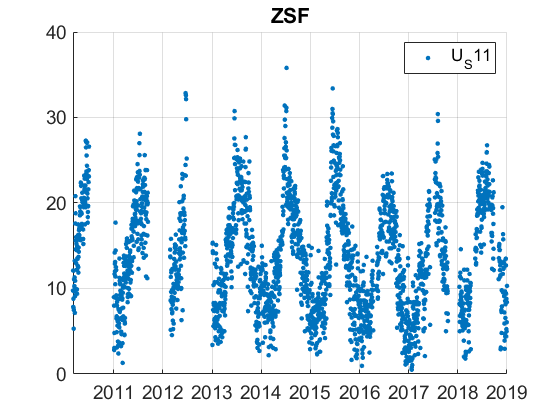

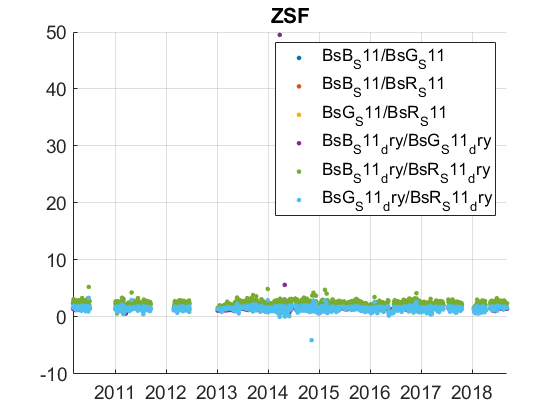

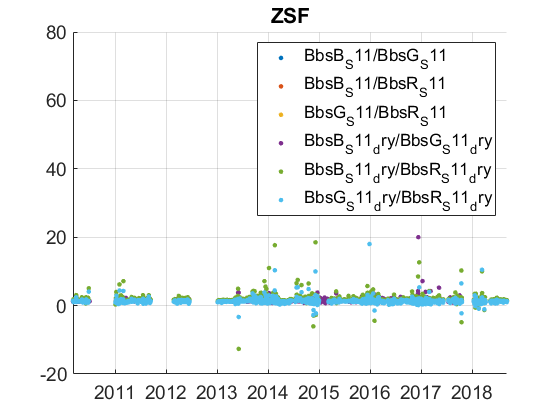

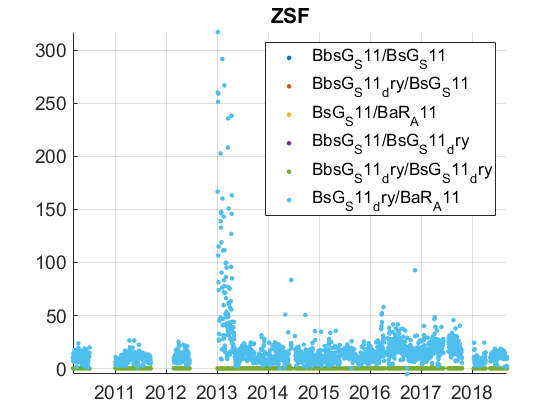

%  prctile(ZSF_rd.U0_S,[5 50 95])
%  prctile(ZSF_rd.U1_S,[5 50 95])
% prctile(ZSF_rd.Uu1_S,[5 50 95])
plotFigControl(ZSF_rd,ZSF_st.name);

% 1 size cut, ok
% sc: ok, no negatives,no clear seasonal cycle

%data send by colleague Jia
maap09=read_nasa_ames('MAAP_2009.nas','M:/pay-prod/Aerosol_actris_trend/data/zsf/' );

 Reading: M:/pay-prod/Aerosol_actris_trend/data/zsf/MAAP_2009.nas


maap10=read_nasa_ames('MAAP_2010.nas','M:/pay-prod/Aerosol_actris_trend/data/zsf/' );

 Reading: M:/pay-prod/Aerosol_actris_trend/data/zsf/MAAP_2010.nas


maap11=read_nasa_ames('MAAP_2011.nas','M:/pay-prod/Aerosol_actris_trend/data/zsf/' );

 Reading: M:/pay-prod/Aerosol_actris_trend/data/zsf/MAAP_2011.nas


maap12=read_nasa_ames('MAAP_2012.nas','M:/pay-prod/Aerosol_actris_trend/data/zsf/' );

 Reading: M:/pay-prod/Aerosol_actris_trend/data/zsf/MAAP_2012.nas


maap13=read_nasa_ames('MAAP_2013.nas','M:/pay-prod/Aerosol_actris_trend/data/zsf/' );

 Reading: M:/pay-prod/Aerosol_actris_trend/data/zsf/MAAP_2013.nas


maap141=read_nasa_ames('MAAP_2014_1.nas','M:/pay-prod/Aerosol_actris_trend/data/zsf/' );

Error using read_nasa_ames (line 23)
No file: M:/pay-prod/Aerosol_actris_trend/data/zsf/MAAP_2014.nas

maap142=read_nasa_ames('MAAP_2014_2.nas','M:/pay-prod/Aerosol_actris_trend/data/zsf/' );

maap15=read_nasa_ames('MAAP_2015.nas','M:/pay-prod/Aerosol_actris_trend/data/zsf/' );
maap16=read_nasa_ames('MAAP_2016.nas','M:/pay-prod/Aerosol_actris_trend/data/zsf/' );
maap17=read_nasa_ames('MAAP_2017.nas','M:/pay-prod/Aerosol_actris_trend/data/zsf/' );
maap18=read_nasa_ames('MAAP_2018.nas','M:/pay-prod/Aerosol_actris_trend/data/zsf/' );


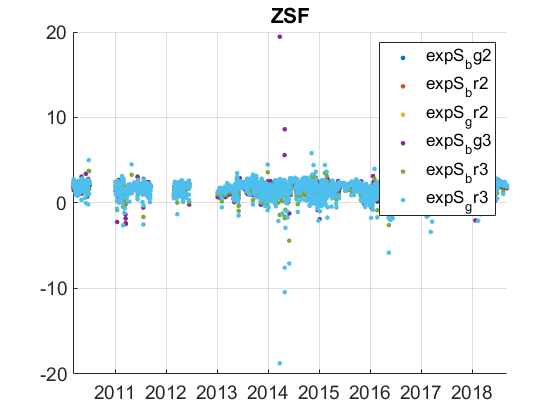

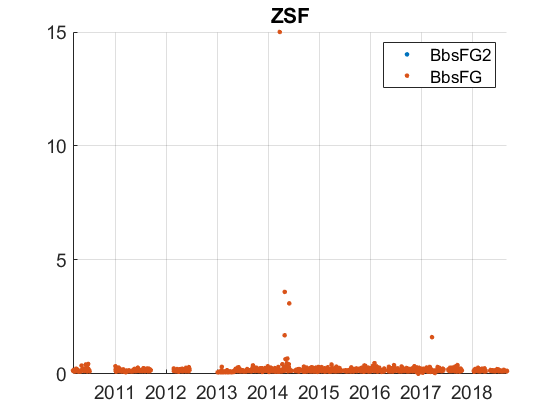

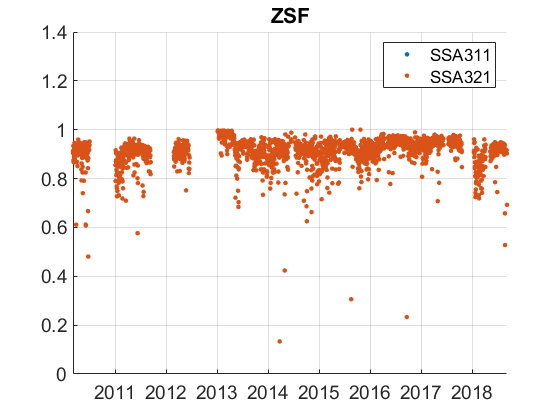

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
ZSF_cal=compute_exp_SSA(ZSF_rd,lambdaSC, lambdaAE);
plotFigControl_cal(ZSF_cal, ZSF_st.name);

%Questions:
%problems:


ZSF_tr=ZSF_rd;
ZSF_tr.y=year(ZSF_tr.Time);
% begin at the beginning of a year: 2009 for abs, 2011 for scat: too short:

%end: 2018 --> only 9/10 years
 P=timerange('2009-01-01','2019-01-01');
ZSF_tr=ZSF_tr(P,:);

% PM1: 2012-2015: too short, not to analyse
%abs: use AE31 also only until end of 2015.
names=fieldnames(ZSF_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1"]) |  contains(names,["Q";"X";"B1_";"G1_";"R1_";"B0_A";"G0_A";"R0_A"]);
N=names(c);
for i=1:length(N)
    ZSF_tr.(N{i})=[];
end

% Scat mid April-10 June 2013 to invalidate (working outside: to be
% confirmed by Ralf Sohmer)
% % 
% % p1=timerange('2013-04-15','2013-06-10');
% % c=startsWith(names,["Bs";"Bbs";"U"]);
% % N=names(c);
% % for i=1:length(N)
% %     ZSF_tr.(N{i})(p1)=NaN;
% % end
%where is MAAP used ??
%RH < 30% at the beginning:  trend on RH but no trend on dry on dry
ZSF_cal2=compute_exp_SSA(ZSF_tr,lambdaSC, lambdaAE);
%do not compute trend on B and R
ZSF_tr.BsB_S11=[];
ZSF_tr.BsB_S11_dry=[];
ZSF_tr.BsR_S11=[];
ZSF_tr.BsR_S11_dry=[];
ZSF_tr.BbsB_S11=[];
ZSF_tr.BbsB_S11_dry=[];
ZSF_tr.BbsR_S11=[];
ZSF_tr.BbsR_S11_dry=[];
ZSF_tr=outerjoin(ZSF_tr, ZSF_cal2);

ZSF_tr.expS_br2=[];
ZSF_tr.expS_br3=[];
ZSF_tr.expS_gr2=[];
ZSF_tr.expS_gr3=[];
%SSA is clearly decreasing, probably because of the RH decrease in the first 3 years. It seem that there is a real decrease of both scat and SSA since 2013.

ZSF_result= all_trend_STN(ZSF_tr,ZSF_st); 
% scat: the first 3 years are incomplete: not trend for neph and SSA.

ZSF_result_D=ZSF_result;
ZSF_result_D=ZSF_result_D(strcmp(ZSF_result_D.parameter,'BaR_A11')==1,:);